# **Matlab案例代码解析**

## 2. 典型绘图案例

### 2.2 二维绘图

#### 2.2.12 两个坐标轴的 x 轴合并在一起

颜值即正义；

**颜色模板参考：**[**60套优雅的颜色模板**](https://zhuanlan.zhihu.com/p/444970597)

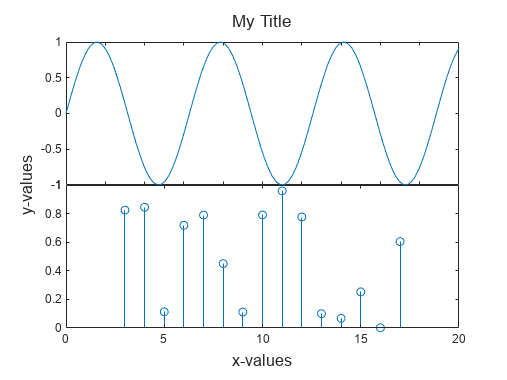

clear;clc;close all;
% 获取到颜色
x1 = linspace(0,20,100);
y1 = sin(x1);
x2 = 3:17;
y2 = rand(1,15);

% Create plots.
t = tiledlayout(2,1);
ax1 = nexttile;
plot(ax1,x1,y1)
ax2 = nexttile;
stem(ax2,x2,y2)

% Link the axes
linkaxes([ax1,ax2],'x');
% Add shared title and axis labels
title(t,'My Title')
xlabel(t,'x-values')
ylabel(t,'y-values')

% Move plots closer together
xticklabels(ax1,{})
t.TileSpacing = 'none'; %将块间距离置0

% exportgraphics(gcf , 'abc.png','Resolution',600); % 600DPI PNG格式